% Con riferimento al quesito precedente, si chiede il calcolo
% dell'incertezza della misura di b, note quelle delle misure di c, α, β.
% Gli errori in ingresso sono indipendenti.
syms a c alpha beta real

alpha_deg = 35.2; % angolo al punto A (gradi)
beta_deg = 48.1; % angolo al punto B (gradi)
alpha_rad = alpha_deg * pi / 180

alpha_rad = 0.6144

beta_rad = beta_deg * pi / 180

beta_rad = 0.8395


Ur_c = 0.01 % WCU relativa di c

Ur_c = 0.0100

Ur_alpha = 0.01 % WCU relativa di alpha

Ur_alpha = 0.0100

Ur_beta = 0.01 % WCU relativa di beta

Ur_beta = 0.0100


b = c * sin(beta) / sin(alpha+beta)

$$b = \frac{c\,\sin\left(\beta \right)}{\sin\left(\alpha +\beta \right)}$$

h = b * sin(alpha)

$$h = \frac{c\,\sin\left(\alpha \right)\,\sin\left(\beta \right)}{\sin\left(\alpha +\beta \right)}$$


cr_c = double(diff(b, c) * c / b)

cr_c = 1

cr_alpha = double(subs(diff(b, alpha) * alpha / b, [alpha, beta], [alpha_rad, beta_rad]))

cr_alpha = -0.0722

cr_beta = double(subs(simplify(diff(b, beta) * beta / b), [alpha, beta], [alpha_rad, beta_rad]))

cr_beta = 0.6546


ur_c = Ur_c / sqrt(3);
ur_alpha = Ur_alpha / sqrt(3);
ur_beta = Ur_beta / sqrt(3);

Ur_b = abs(cr_c) * Ur_c + abs(cr_alpha) * Ur_alpha + abs(cr_beta) * Ur_beta

Ur_b = 0.0173

ur_b = sqrt((cr_c*ur_c)^2 + (cr_alpha*ur_alpha)^2 + (cr_beta*ur_beta)^2)

ur_b = 0.0069

% Si chiede il calcolo dell'incertezza delle misure di b e di h, note quelle delle misure di c, α, β.
% Nel seguito, si intende:
x = [c, alpha, beta] % vettore delle grandezze in ingresso

$$x = \left(\begin{array}{ccc} c & \alpha & \beta \end{array}\right)$$

% theta = [b;h] % vettore delle grandezze in uscita

alpha_deg = 35.2; % angolo al punto A (gradi)
beta_deg = 48.1; % angolo al punto B (gradi)
alpha_rad = alpha_deg * pi / 180;
beta_rad = beta_deg * pi / 180;
Ur = 0.01*ones(3,1) % WCU relativa di x

Ur =     0.0100
    0.0100
    0.0100



Cr = double(subs(jacobian(theta, x) .* x ./ theta, [alpha, beta], [alpha_rad, beta_rad])) % matrice dei coefficienti relativi di sensibilità di theta rispetto a x

Cr =     1.0000   -0.0722    0.6546
    1.0000    0.7987    0.6546


Ur_theta = abs(Cr) * Ur % WCU relativa di theta

Ur_theta =     0.0173
    0.0245


ur = Ur / sqrt(3) % SU relativa di x

ur =     0.0058
    0.0058
    0.0058


Sigmar = diag(ur)^2 % matrice covarianza relativa di x

Sigmar = 1.0e-04 *

    0.3333         0         0
         0    0.3333         0
         0         0    0.3333



Sigmar_theta = Cr * Sigmar * Cr' % matrice covarianza relativa di theta

Sigmar_theta = 1.0e-04 *

    0.4779    0.4570
    0.4570    0.6888


ur_theta = sqrt(diag(Sigmar_theta)) % SU relativa di theta

ur_theta =     0.0069
    0.0083



R_theta = diag(ur_theta)^-1 * Sigmar_theta * diag(ur_theta)^-1 % coefficiente di correlazione tra gli errori di misura su b e h

R_theta =     1.0000    0.7964
    0.7964    1.0000


rho = R_theta(1,2)

rho = 0.7964

% Un punto materiale si muove di moto uniformemente accelerato, cioè con la legge
% x(t) = x0 + v0*t + 1/2*a*t^2
%
% I parametri incogniti sono:
% theta = [x0; v; a]
%
% Sono forniti il vettore t degli istanti in cui si misurano i valori x, e il
% vettore y dei risultati delle misure. Calcolare la stime OLS richieste.
% 
% ATTENZIONE: la matrice A deve essere congruente alla definizione di theta.

%==============================
% Dati, e codice che li genera (il codice NON VA MAI RIPORTATO NELLA SOLUZIONE)
N = 30;
dt = 1e-1;
t = linspace(0, N, N)' * dt

t =          0
    0.1034
    0.2069
    0.3103
    0.4138
    0.5172
    0.6207
    0.7241
    0.8276
    0.9310


x0 = 10;
v0 = 34;
a = 135;
theta = [x0; v0; a];
x = x0 + v0*t + 1/2*a*t.^2

x =    10.0000
   14.2396
   19.9239
   27.0529
   35.6266
   45.6451
   57.1082
   70.0161
   84.3686
  100.1659


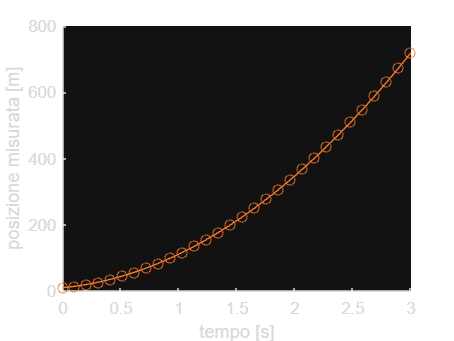

y = x + randn(N, 1) * 0.05;

figure(1)
hold on;
plot(t, x)
plot(t, y, 'o-')
xlabel('tempo [s]')
ylabel('posizione misurata [m]')


A = [ones(N,1) t t.^2/2] % matrice dei regressori, assumendo come vettore dei parametri theta = [x0; v0; a]

A =     1.0000         0         0
    1.0000    0.1034    0.0054
    1.0000    0.2069    0.0214
    1.0000    0.3103    0.0482
    1.0000    0.4138    0.0856
    1.0000    0.5172    0.1338
    1.0000    0.6207    0.1926
    1.0000    0.7241    0.2622
    1.0000    0.8276    0.3424
    1.0000    0.9310    0.4334


Q = (A'*A)^-1;
C = Q*A' % matrice pseudoinversa di A

C =     0.2633    0.2286    0.1960    0.1653    0.1367    0.1101    0.0855    0.0629    0.0423    0.0238    0.0073   -0.0073   -0.0198   -0.0302   -0.0387   -0.0452   -0.0496   -0.0520   -0.0524   -0.0508   -0.0472   -0.0415   -0.0339   -0.0242   -0.0125    0.0012    0.0169    0.0347    0.0544    0.0762
   -0.3450   -0.2822   -0.2236   -0.1692   -0.1189   -0.0729   -0.0310    0.0067    0.0403    0.0696    0.0948    0.1158    0.1326    0.1453    0.1538    0.1581    0.1582    0.1541    0.1459    0.1335    0.1169    0.0962    0.0712    0.0421    0.0088   -0.0286   -0.0703   -0.1161   -0.1661   -0.2202
    0.1884    0.1494    0.1132    0.0798    0.0492    0.0213   -0.0037   -0.0260   -0.0455   -0.0622   -0.0761   -0.0872   -0.0956   -0.1012   -0.1039   -0.1039   -0.1012   -0.0956   -0.0872   -0.0761   -0.0622   -0.0455   -0.0260   -0.0037    0.0213    0.0492    0.0798    0.1132    0.1494    0.1884


P = A*C;
theta_hat = C * y % vettore dei parametri stimati 

theta_hat =    10.0154
   34.0346
  134.9709


x0_hat =  theta_hat(1) % stima OLS del parametro x0

x0_hat = 10.0154

a_hat = theta_hat(3) % stima OLS del parametro a

a_hat = 134.9709

x_hat = P * y; % vettore dei campioni di segnale stimati

clf; clc; clear;

% In un problema OLS dello stesso tipo del precedente, eseguire la valutazione di tipo A
% dell'incertezza, come specificato nella sezione "domande".
%
% Gli errori da cui sono affette le misure in ingresso sono i.i.d.

N = 30;
dt = 1e-1;
t = linspace(0, N, N)' * dt

t =          0
    0.1034
    0.2069
    0.3103
    0.4138
    0.5172
    0.6207
    0.7241
    0.8276
    0.9310


x0 = 10;
v0 = 34;
a = 135;
theta = [x0; v0; a];
x = x0 + v0*t + 1/2*a*t.^2

x =    10.0000
   14.2396
   19.9239
   27.0529
   35.6266
   45.6451
   57.1082
   70.0161
   84.3686
  100.1659


y = x + randn(N, 1) * 50;
A = [ones(N,1) t t.^2/2] % matrice dei regressori, assumendo come vettore dei parametri theta = [x0; v0; a]

A =     1.0000         0         0
    1.0000    0.1034    0.0054
    1.0000    0.2069    0.0214
    1.0000    0.3103    0.0482
    1.0000    0.4138    0.0856
    1.0000    0.5172    0.1338
    1.0000    0.6207    0.1926
    1.0000    0.7241    0.2622
    1.0000    0.8276    0.3424
    1.0000    0.9310    0.4334


Q = (A'*A)^-1;
C = Q*A' % matrice pseudoinversa di A

C =     0.2633    0.2286    0.1960    0.1653    0.1367    0.1101    0.0855    0.0629    0.0423    0.0238    0.0073   -0.0073   -0.0198   -0.0302   -0.0387   -0.0452   -0.0496   -0.0520   -0.0524   -0.0508   -0.0472   -0.0415   -0.0339   -0.0242   -0.0125    0.0012    0.0169    0.0347    0.0544    0.0762
   -0.3450   -0.2822   -0.2236   -0.1692   -0.1189   -0.0729   -0.0310    0.0067    0.0403    0.0696    0.0948    0.1158    0.1326    0.1453    0.1538    0.1581    0.1582    0.1541    0.1459    0.1335    0.1169    0.0962    0.0712    0.0421    0.0088   -0.0286   -0.0703   -0.1161   -0.1661   -0.2202
    0.1884    0.1494    0.1132    0.0798    0.0492    0.0213   -0.0037   -0.0260   -0.0455   -0.0622   -0.0761   -0.0872   -0.0956   -0.1012   -0.1039   -0.1039   -0.1012   -0.0956   -0.0872   -0.0761   -0.0622   -0.0455   -0.0260   -0.0037    0.0213    0.0492    0.0798    0.1132    0.1494    0.1884


P = A*C;
x_hat = P * y; % vettore dei campioni di segnale stimati

cp = 0.95

cp = 0.9500


% A = % matrice dei regressori, assumendo come vettore dei parametri theta = [x0; v0; a]
e_hat = y - x_hat % vettore degli errori in ingresso stimati (residui)

e_hat =     6.3280
  -40.0581
  -83.9857
   83.5819
   52.0949
   -1.6762
   35.1369
   22.7245
  -34.9861
 -102.9922


nu = N - size(theta, 1) % numero di gradi di libertà nella valutazione di tipo A dell'incertezza

nu = 27

SSR = sum(e_hat.^2)

SSR = 5.6517e+04

u0 = sqrt(SSR/nu) % incertezza standard di tipo A delle misure in ingresso (scalare)

u0 = 45.7519

Sigma_theta = u0^2 * Q; % matrice covarianza di tipo A dei parametri stimati theta_hat
u_theta = sqrt(diag(Sigma_theta)) % incertezza standard di tipo A dei parametri stimati theta_hat

u_theta =    23.4769
   36.2265
   23.3365


Sigma_x = u0^2 * P; % matrice covarianza di tipo A dei campioni di segnale stimati x_hat
u_x = sqrt(diag(Sigma_x)); % incertezza standard di tipo A del segnale stimato x_hat
k_cp = tinv((1+cp)/2, nu);
U_x = u_x * k_cp;
x_U = x_hat + U_x % limite superiore della banda di confidenza con prob. cp per il segnale x

x_U =    75.2809
   63.4400
   54.6767
   49.0608
   46.6639
   47.5364
   51.6722
   58.9784
   69.2782
   82.3507


x_L = x_hat - U_x % limite inferiore della banda di confidenza con prob. cp per il segnale x

x_L =   -21.0603
  -20.5742
  -18.5531
  -15.0668
  -10.1868
   -3.9635
    3.6091
   12.6240
   23.2580
   35.7319


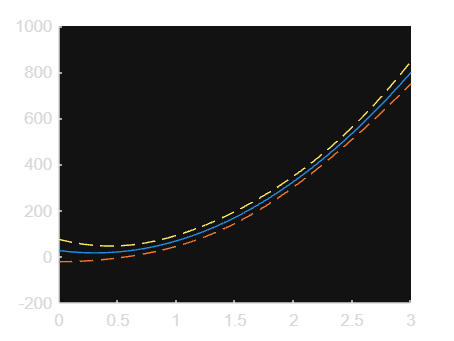


hold on;
plot(t, x_hat)
plot(t, [x_L, x_U], '--')


clf; clc; clear;

% Con riferimento a una stima OLS per cui si è eseguita la valutazione di
% tipo A della SU in ingresso, dire qual è la pdf (stimata) degli errori in
% ingresso e degli errori in uscita, e la WCU in ingresso. Utilizzare i
% dati forniti.

N = 1000;
dt = 1e-1;
t = linspace(0, N, N)' * dt

t =          0
    0.1001
    0.2002
    0.3003
    0.4004
    0.5005
    0.6006
    0.7007
    0.8008
    0.9009


x0 = 10;
v0 = 34;
a = 135;
theta = [x0; v0; a];
x = x0 + v0*t + 1/2*a*t.^2

x = 1.0e+05 *

    0.0001
    0.0001
    0.0002
    0.0003
    0.0003
    0.0004
    0.0005
    0.0007
    0.0008
    0.0010


y = x + unifrnd(0, 1, [N, 1]) * 50;
A = [ones(N,1) t t.^2/2] % matrice dei regressori, assumendo come vettore dei parametri theta = [x0; v0; a]

A = 1.0e+03 *

    0.0010         0         0
    0.0010    0.0001    0.0000
    0.0010    0.0002    0.0000
    0.0010    0.0003    0.0000
    0.0010    0.0004    0.0001
    0.0010    0.0005    0.0001
    0.0010    0.0006    0.0002
    0.0010    0.0007    0.0002
    0.0010    0.0008    0.0003
    0.0010    0.0009    0.0004


Q = (A'*A)^-1;
C = Q*A' % matrice pseudoinversa di A

C =     0.0090    0.0089    0.0089    0.0089    0.0088    0.0088    0.0087    0.0087    0.0087    0.0086    0.0086    0.0086    0.0085    0.0085    0.0085    0.0084    0.0084    0.0084    0.0083    0.0083    0.0083    0.0082    0.0082    0.0082    0.0081    0.0081    0.0081    0.0080    0.0080    0.0079    0.0079    0.0079    0.0078    0.0078    0.0078    0.0077    0.0077    0.0077    0.0076    0.0076    0.0076    0.0075    0.0075    0.0075    0.0074    0.0074    0.0074    0.0073    0.0073    0.0073
   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0

P = A*C;
x_hat = P * y;
e_hat = y - x_hat

e_hat =   -13.8609
   11.9409
   11.5676
   20.8882
  -16.7157
   -0.8119
  -16.3110
   23.0197
   -8.9497
  -17.7963


e = y - x;
nu = N - size(theta, 1)

nu = 997

SSR = sum(e_hat.^2)

SSR = 2.0249e+05

u0 = sqrt(SSR/nu)

u0 = 14.2511

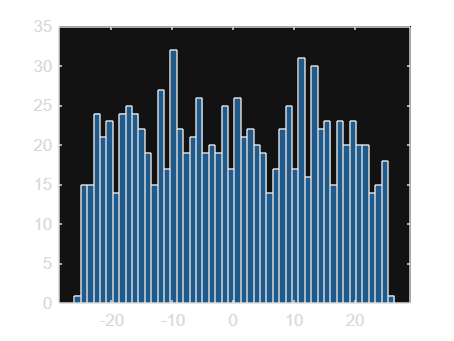


histogram(e_hat, 'NumBins', 50)


pdf_y = 'unif' % pdf degli errori sulle misure y

pdf_y = 'unif'

U0 = u0 * sqrt(3) % WCU stimata in ingresso

U0 = 24.6837


Sigma_theta = u0^2 * Q;
u_theta = sqrt(diag(Sigma_theta))

u_theta =     1.3493
    0.0623
    0.0012


pdf_theta = 'normf'; % pdf degli errori sulle stime theta_hat

pdf_theta = 'normf'

pdf_x = 'normf'; % pdf degli errori sulle stime x_hat

pdf_x = 'normf'


%==============================
% Nota
% Per specificare la pdf, scegliere tra:
% 'unif' % uniforme (rettangolare)
% 'tri' % triangolare
% 'trap' % trapezoidale
% 'asin' % arcoseno
% 'normf' % approx normale, ma con code finite (supporto finito)
% 'norm' % normale

% Si collega un generatore con resistenza interna Rgen a un filtro
% CR come in figura. Si collegano i due canali dell'oscilloscopio all'ingresso
% e all'uscita del circuito CR.
% Con il circuito si misura sia la risposta al gradino, sia la risposta a
% un segnale sinusoidale (FRF con sinusoide single-tone).

R = 300 % resistenza del circuito (ohm)

R = 300

C = 2e-9 % capacità del circuito (F)

C = 2.0000e-09

s = tf('s') % variabile s della trasformata di Laplace

s =
 
  s
 
Continuous-time transfer function.
Model Properties


f = 3e5 % frequenza del segnale sinusoidale (Hz)

f = 300000

w = 2*pi*f

w = 1.8850e+06


Rgen = 50; % resistenza interna del generatore
R1 = Rgen + R;
tau1 = R1*C

tau1 = 7.0000e-07

Hdot1 = R / (R1 + 1/(s*C)) % funzione di trasferimento misurando la risposta al gradino, calcolata in s

Hdot1 =
 
    6e-07 s
  -----------
  7e-07 s + 1
 
Continuous-time transfer function.
Model Properties


fc1 = 1 / (2*pi*tau1) % frequenza di taglio teorica di Hdot1 (Hz)

fc1 = 2.2736e+05

tau = R*C

tau = 6.0000e-07

Hdot = R / (R + 1/(s*C)) % funzione di trasferimento misurando la risposta a una sinusoide single-tone, calcolata in s

Hdot =
 
    6e-07 s
  -----------
  6e-07 s + 1
 
Continuous-time transfer function.
Model Properties


fc = 1 / (2*pi*tau) % frequenza di taglio teorica di Hdot (Hz)

fc = 2.6526e+05

H = (f/fc) / sqrt(1 + (f/fc)^2) % risposta di ampiezza al segnale sinusoidale, alla frequenza f

H = 0.7492

phiH = pi/2 - atan(f/fc) % risposta di fase al segnale sinusoidale, alla frequenza f

phiH = 0.7240

phiH_deg = phiH * 180 / pi

phiH_deg = 41.4829

H_dB = 20*log10(H)

H_dB = -2.5086

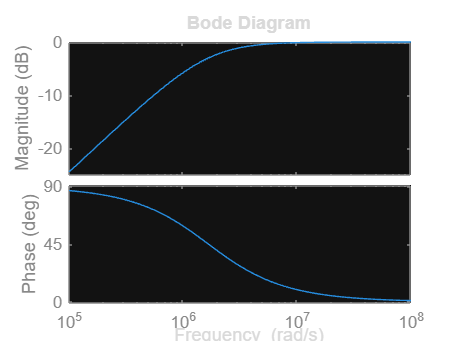

bode(Hdot)

filtro = 2 % tipo di filtro che realizza il circuito

filtro = 2


%==============================
% Note
% Si consideri se Rgen interviene nella misura, nei due casi (misura di
% risposta al gradino, misura di FRF con sinusoide single-tone).
% Quando si misura la risposta al gradino si utilizza solo la tensione V2
% misurata al canale 2 dell'oscilloscopio, e non si tiene conto di V1.
% Quando si misura la risposta al segnale sinusoidale, si confrontano le
% tensioni V2 e V1.
%
% Suggerimento: calcolare con carta e penna Hdot1 e Hdot, e in base ai calcoli
% rispondere alle domande sulle funzioni di trasferimento.
%
% Per la resistenza Rgen del generatore, utilizzare il valore standard del generatore utilizzato in laboratorio.
%
% Per rispondere alla domanda sul tipo di filtro, usare la seguente codifica:
% filtro = 1 % passa-basso
% filtro = 2 % passa-alto
% filtro = 3 % passa-banda
% filtro = 4 % elimina-banda
% filtro = 5 % passa-tutto

% Con riferimento al circuito CR considerato, si misurano con l'oscilloscopio le sinusoidi 
% in ingresso e in uscita, come in figura (indicativa).
% Si misuri la risposta di ampiezza, la frequenza di taglio, e la capacità, valutando l'incertezza.
% Gli errori su Vpp1, Vpp2, f sono indipendenti.

Vpp1 = 6 % tensione picco-picco in ingresso (V)

Vpp1 = 6

Vpp2 = 2.95 % tensione picco-picco in uscita (V)

Vpp2 = 2.9500

R = 250 % resistenza del circuito CR (ohm)

R = 250

f = 3e5 % frequenza della sinusoide (Hz)

f = 300000


Ur_Vpp1 = 1e-3 % incertezza relativa nella misura di Vpp1

Ur_Vpp1 = 1.0000e-03

Ur_Vpp2 = 2e-3 % incertezza relativa nella misura di Vpp2

Ur_Vpp2 = 0.0020

Ur_f = 0.5e-3 % incertezza relativa nella misura di f

Ur_f = 5.0000e-04

Ur_R = 1e-3 % incertezza relativa nella misura di R

Ur_R = 1.0000e-03


H = Vpp2/Vpp1 % risposta di ampiezza misurata

H = 0.4917

fc = f * sqrt(1 - H^2) / H % frequenza di taglio misurata dalla risposta di ampiezza

fc = 5.3133e+05

Ur_H = Ur_Vpp1 + Ur_Vpp2 % WCU relativa di H

Ur_H = 0.0030

Ur = [Ur_H; Ur_f] % vettore colonna delle WCU relative di x = [H; f]

Ur =     0.0030
    0.0005



syms f_ H_ real;
fc_ = f_ * sqrt(1 - H_^2) / H_;
simplify(diff(fc_, H_) .* H_ ./ fc_)

$$ans = \frac{1}{{\mathrm{H\_}}^{2}-1}$$

simplify(diff(fc_, f_) .* f_ ./ fc_)

$$ans = 1$$

Cr = [1 / (H^2 - 1), 1] % matrice dei coefficienti relativi di sensibilità di fc rispetto a x = [H; f]

Cr =    -1.3188    1.0000


Ur_fc = abs(Cr) * Ur % WCU relativa di fc

Ur_fc = 0.0045

ur_H = sqrt(Ur_Vpp1.^2/3 + Ur_Vpp2.^2/3) % incertezza standard relativa di H

ur_H = 0.0013

ur = [ur_H; Ur_f/sqrt(3)] % vettore colonna delle incertezze standard relative di x = [H; f]

ur =     0.0013
    0.0003


ur_fc = sqrt(Cr.^2 * ur.^2) % incertezza standard relativa di fc

ur_fc = 0.0017


tau = 1/(2*pi*fc);
CH = tau/R % capacità del circuito CR misurata dalla risposta di ampiezza H

CH = 1.1982e-09

cr_tau = 1;
cr_R = -1;
Ur_tau = Ur_fc;
Ur_CH = abs(cr_tau) * Ur_tau + abs(cr_R) * Ur_R % WCU relativa nella misura di CH

Ur_CH = 0.0055

ur_R = Ur_R/sqrt(3);
ur_CH = sqrt(ur_fc^2 + ur_R^2) % incertezza standard relativa nella misura di CH

ur_CH = 0.0018

% Si esegue una misura di tensione continua con il multimetro Agilent 34401A, 
% le cui caratteristiche sono in figura. 
% La misura è eseguita con la portata più piccola compatibile con la misura.
% Calcolare l'incertezza (di caso peggiore).

V = -11.5 % valore di tensione continua misurato (V)

V = -11.5000


VFS = 100

VFS = 100


Ur_reading_pc = 0.0045 % "reading error percentuale": il numero scritto nelle specifiche

Ur_reading_pc = 0.0045

U_range_pcFS = 0.0006 % "range error in percentuale del fondo scala": il numero scritto nelle specifiche

U_range_pcFS = 6.0000e-04

U_reading = Ur_reading_pc / 100 * abs(V) % "reading error" assoluto (incertezza assoluta dovuta al reading error)

U_reading = 5.1750e-04

U_range = U_range_pcFS / 100 * VFS % "range error" assoluto (incertezza assoluta dovuta al range error)

U_range = 6.0000e-04

U_V = U_reading + U_range % incertezza assoluta totale

U_V = 0.0011


%==============================
% Nota:
% Fare riferimento ai dati "1 Year". La specifica sulla temperatura è da ignorare 
% (temperatura compresa tra 18 e 28 °C).